clear all;
VLFEAT_DIR = 'VLFEATROOT';
run(fullfile(VLFEAT_DIR,'/toolbox/vl_setup'));
vl_version;

0.9.20


**i) Compute the F-score when different parameters of the algorithm are used.**

In this section, we are going to focus on how PHOW step and size parameters influence the mean F1 score. 

The number of words was fixed to a low value of 30 on purpose. It is known that low number of words tends to generalise too much and mix features together causing a low performance of the model. However, there may be a combination of step and size that could overcome the deficiency of using a low number of words. The categories used for the paramter optimization are: Background, Faces, Easy Faces, Leopards and Motorbikes, the default categories in the TinyProblem settings.

The sizes and steps values considered ranges from 3 to 12 in unit steps.  

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.
vl_phow: color space: gray
vl_phow: color space: gray
vl_phow: image size: 170 x 252
vl_phow: sizes: [ 3]
vl_dsift: image size         [W, H] = [170, 252]
vl_dsift: bounds:            [minX,minY,maxX,maxY] = [1, 1, 170, 252]
vl_dsift: subsampling steps: stepX=3, stepY=3
vl_dsift: num bins:          [numBinT, numBinX, numBinY] = [8, 4, 4]
vl_dsift: descriptor size:   128
vl_dsift: bin sizes:         [binSizeX, binSizeY] = [3, 3]
vl_dsift: flat window:       yes
vl_dsift: window size:       1.5
vl_dsift: num of features:   4374
vl_phow: color space: gray
vl_phow: color space: gray
vl_phow: image size: 500 x 360
vl_phow: sizes: [ 3]
vl_dsift: image size         [W, H] = [500, 360]
vl_dsift: bounds:            [minX,minY,maxX,maxY] = [1, 1, 500, 360]
vl_dsift: subsampling steps: stepX=3, stepY=3
vl_dsift: num bins:          [numBinT, numBinX, numBinY] = [8, 4, 4]
vl_dsift: descriptor size:   128
vl_dsift

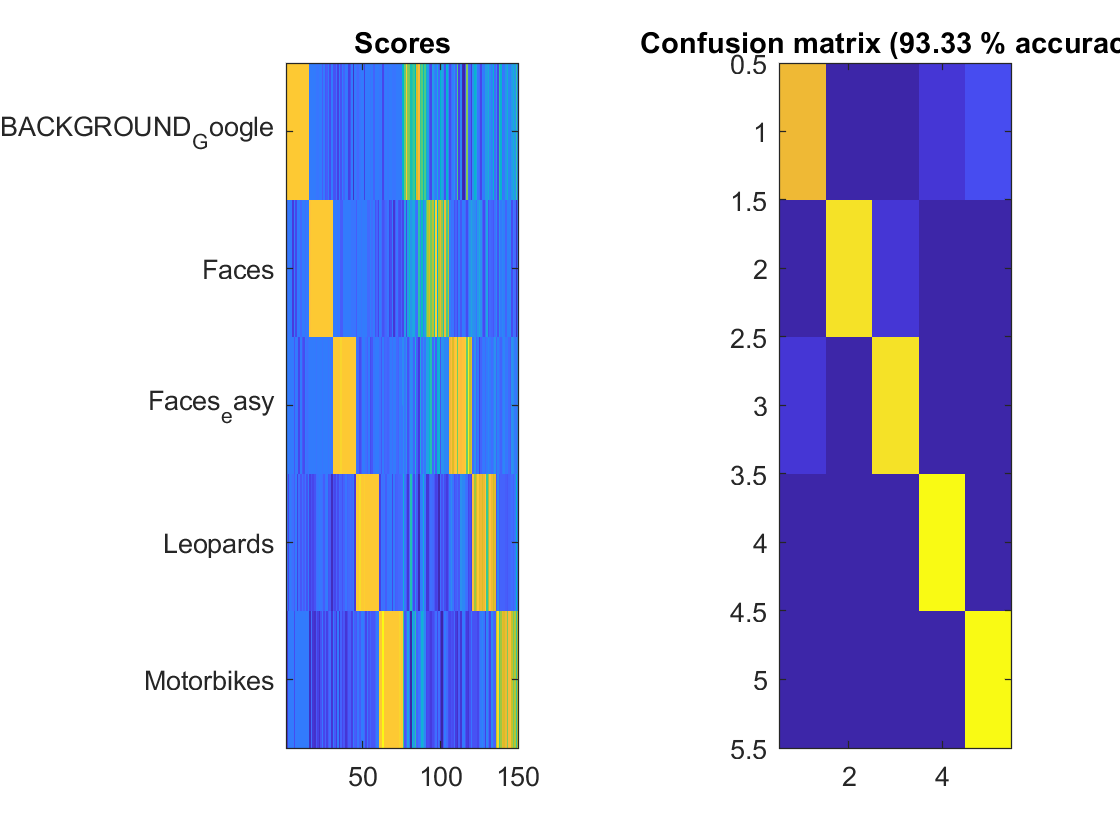

TinyCat = {'BACKGROUND_Google', 'Faces', 'Faces_easy', 'Leopards', 'Motorbikes'};

sizes = [3, 4, 5, 6, 7, 8, 9, 10, 11, 12];
steps = [3, 4, 5, 6, 7, 8, 9, 10, 11, 12];

[X,Y] = meshgrid(steps, sizes);
Z = zeros(size(X));
for i = 1:length(sizes)
    for j = 1:length(steps)
        opt = {'Verbose', 2, 'Sizes', sizes(i), 'Step', steps(j)};
        modified_phow_caltech101(TinyCat, 'f1-tests', 30, opt);
        load(fullfile('data','f1-tests-result.mat'));
        [F1, Precision, Recall] = f1Score(confus);
        Z(i,j) = mean(F1);
    end
end

Plotting the results:

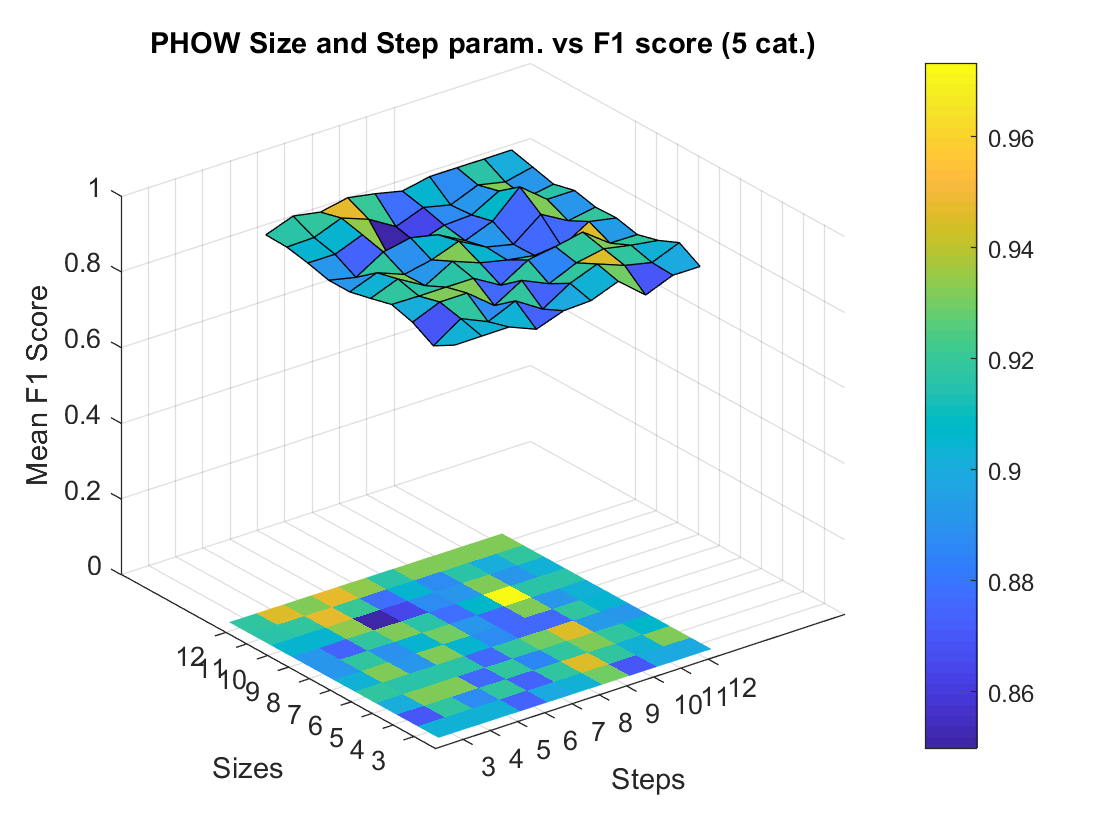

figure
surf(X,Y,Z), hold on, imagesc(Z), colorbar;
set(gca, 'ytick', 1:length(sizes), 'yticklabel', sizes); ylabel("Sizes");
set(gca, 'xtick', 1:length(steps), 'xticklabel', steps); xlabel("Steps");
zlabel("Mean F1 Score");
title("PHOW Size and Steps param. vs F1 score (5 cat.)");

The figure shows the surface of mean F1 score across 100 combinations of sizes and step values. The mean F1 scores goes from 0.85 to a maximum of 0.9733, the maximum is obtained with a size value of 9 and and step value of 10.  However, the surface seems a bit noisy and there is not a flat area of robust values. 